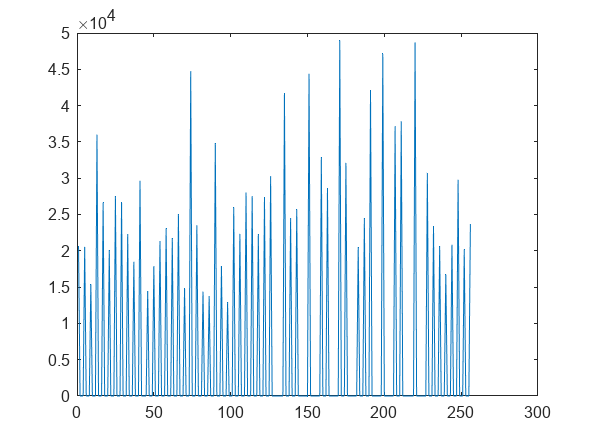

close all; clc; clearvars;
T_buenacalidad_revisadas = readtable('metadataCALIDADCORRECTA.csv');
[n, m] = size(T_buenacalidad_revisadas);

roi = imread(['ROI', T_buenacalidad_revisadas.image{2}]);

red_channel = roi(:, :, 1);
green_channel = roi(:, :, 2);
blue_channel = roi(:, :, 3);
I_gray = rgb2gray(roi);

se = strel('disk', 30); 
canal_verde_sin_vasos = imclose(green_channel, se);
canal_rojo_sin_vasos = imclose(red_channel, se); %el canal rojo no tiene vasos
canal_azul_sin_vasos = imclose(blue_channel, se);
gray_sin_vasos = imclose (I_gray, se);

gray_sin_vasos1 = adapthisteq(gray_sin_vasos);
canal_azul_sin_vasos1 = adapthisteq(canal_azul_sin_vasos);
canal_verde_sin_vasos1 = adapthisteq(canal_verde_sin_vasos);
canal_rojo_sin_vasos1 = adapthisteq(canal_rojo_sin_vasos);

gray_sin_vasos2 = histeq(gray_sin_vasos);
canal_azul_sin_vasos2 = histeq(canal_azul_sin_vasos);
canal_verde_sin_vasos2 = histeq(canal_verde_sin_vasos);
canal_rojo_sin_vasos2 = histeq(canal_rojo_sin_vasos);

e_gris = entropy(I_gray);
e_rojo = entropy(red_channel); % si es mas de 6 bien
e_verde = entropy(green_channel);
e_azul = entropy(blue_channel); % si es menos de 4 -> no usar %a partir de 6 no usar

e_gris1 = entropy(gray_sin_vasos1);
e_rojo1 = entropy(canal_rojo_sin_vasos1); 
e_verde1 = entropy(canal_verde_sin_vasos1);
e_azul1 = entropy(canal_azul_sin_vasos1);

e_gris2 = entropy(gray_sin_vasos2);
e_rojo2 = entropy(canal_rojo_sin_vasos2); 
e_verde2 = entropy(canal_verde_sin_vasos2);
e_azul2 = entropy(canal_azul_sin_vasos2);

% e_gris1 = entropy(gray_sin_vasos);
% e_rojo1 = entropy(canal_rojo_sin_vasos1); 
% e_verde1 = entropy(canal_verde_sin_vasos1);
% e_azul1 = entropy(canal_azul_sin_vasos1);
% 
% e_gris2 = entropy(gray_sin_vasos2);
% e_rojo2 = entropy(canal_rojo_sin_vasos2); 
% e_verde2 = entropy(canal_verde_sin_vasos2);
% e_azul2 = entropy(canal_azul_sin_vasos2);


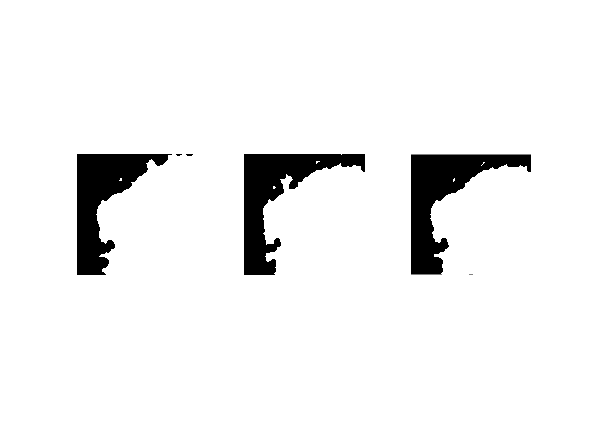

% DISCO
if e_rojo > e_gris 
    disc_thresholdR = 0.7 * max(canal_rojo_sin_vasos2(:)); % Umbral para el disco completo (menos brillo)

    disc_binaryR = canal_rojo_sin_vasos2 > disc_thresholdR; % Segmentación del disco completo 
    disc_binary_comun =disc_binaryR;
    figure; imshow(disc_binary_comun);
else 
    T = multithresh(gray_sin_vasos2, 2);
    disc_binary = gray_sin_vasos2 > T(1);

    T = multithresh(canal_verde_sin_vasos2, 2);
    disc_binaryG = canal_verde_sin_vasos2 > T(1);

%     disc_threshold = 0.5 * max(gray_sin_vasos(:)); % Umbral para el disco completo (menos brillo)
%     disc_binary = gray_sin_vasos > disc_threshold; % Segmentación del disco completo
% 
%     disc_thresholdG = 0.5 * max(canal_verde_sin_vasos(:)); % Umbral para el disco completo (menos brillo) 
%     disc_binaryG = canal_verde_sin_vasos > disc_thresholdG; % Segmentación del disco completo

    disc_binary_comun =  disc_binaryG & disc_binary;
    figure; subplot(1,3,1); imshow(disc_binary);
    subplot(1,3,2); imshow(disc_binaryG);
    subplot(1,3,3); imshow(disc_binary_comun);
end

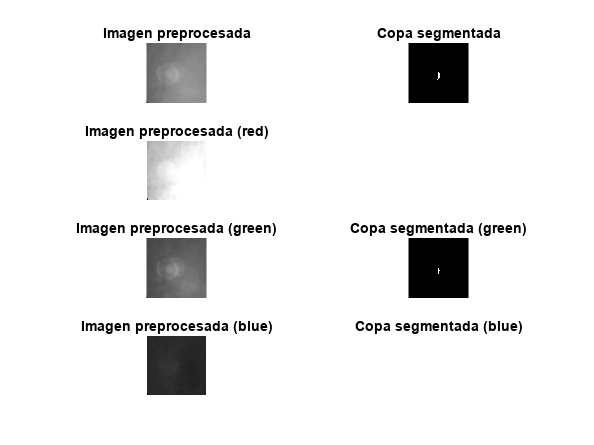


%COPA 
if e_gris > 5 
    cup_threshold = 0.95 * max(gray_sin_vasos(:)); % Umbral para la copa (brillo)
    
    cup_binary = gray_sin_vasos > cup_threshold; % Segmentación de la copa
else 
    cup_binary = ones(size(gray_sin_vasos));
end
if e_verde > 4.5 
    cup_thresholdG = 0.95 * max(canal_verde_sin_vasos(:)); % Umbral para la copa (brillo)
  
    cup_binaryG = canal_verde_sin_vasos > cup_thresholdG; % Segmentación de la copa
else 
    cup_binaryG = ones(size(gray_sin_vasos));
end

if e_azul > 5 
    cup_thresholdB = 0.8 * max(canal_azul_sin_vasos(:)); % Umbral para la copa (brillo)

    cup_binaryB = canal_azul_sin_vasos > cup_thresholdB; % Segmentación de la copa
else 
    cup_binaryB = ones(size(gray_sin_vasos));
end

figure; subplot(4, 2, 1); imshow(gray_sin_vasos); title('Imagen preprocesada');
subplot(4, 2, 2); imshow(cup_binary); title('Copa segmentada');
subplot(4, 2, 3); imshow(canal_rojo_sin_vasos); title('Imagen preprocesada (red)');
% subplot(4, 3, 5); imshow(cup_binaryR); title('Copa segmentada (red)');
subplot(4, 2, 5); imshow(canal_verde_sin_vasos); title('Imagen preprocesada (green)');
subplot(4, 2, 6); imshow(cup_binaryG); title('Copa segmentada (green)');
subplot(4, 2, 7); imshow(canal_azul_sin_vasos); title('Imagen preprocesada (blue)');
subplot(4, 2, 8); imshow(cup_binaryB); title('Copa segmentada (blue)');

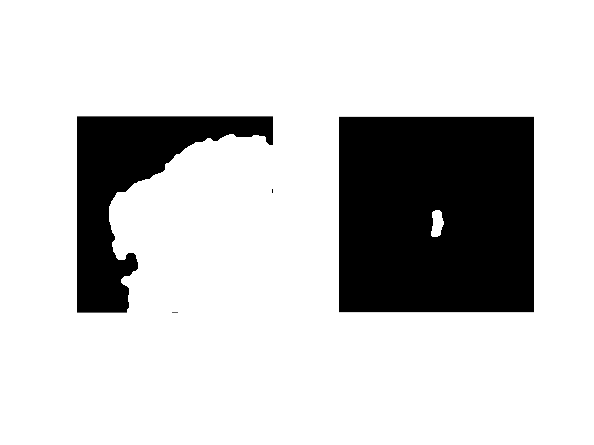


% Operación lógica de intersección para la segmentación de la copa
cup_binary_comun = cup_binary & cup_binaryG & cup_binaryB;

se = strel('disk', 20);
disco = imerode(disc_binary_comun, se);
disco = bwareafilt(disco, 1);
disco = imdilate(disco, se);
copa = bwareafilt(cup_binary_comun, 1);
copa = imdilate(copa, se);

figure; subplot(1,2,1); imshow(disco);
subplot(1,2,2); imshow(copa);

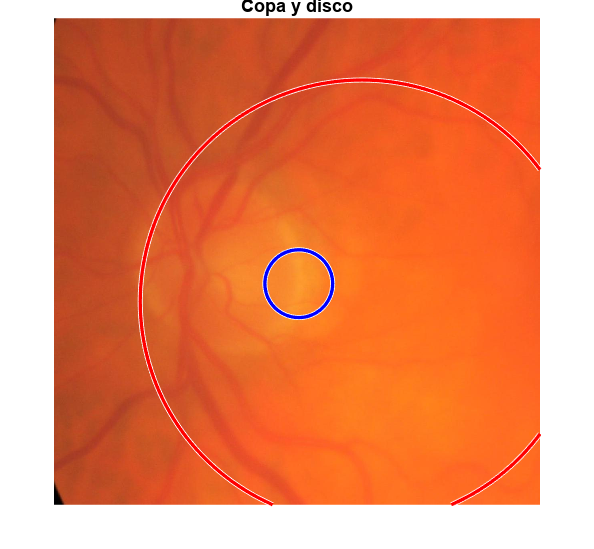


[fila, columna] = find(disco == max(disco(:)));
% Calcula el centroide
centroide_x = mean(columna);
centroide_y = mean(fila);
centro_disco = [centroide_x, centroide_y]; 
% Calcula el radio
ancho_maximo = max(fila) - min(fila);
alto_maximo = max(columna) - min(columna);
radio_disco = max(ancho_maximo, alto_maximo) / 2;

[fila, columna] = find(copa == max(copa(:)));
% Calcula el centroide
centroide_x = mean(columna);
centroide_y = mean(fila);
centro_copa = [centroide_x, centroide_y]; 
% Calcula el radio
ancho_maximo = max(fila) - min(fila);
alto_maximo = max(columna) - min(columna);
radio_copa = max(ancho_maximo, alto_maximo) / 2;

figure; imshow(roi); title('Copa y disco')
% subplot(4,5,i); imshow(roi); title(T_buenacalidad_revisadas.image{i});
hold on;
viscircles(centro_disco, radio_disco, 'EdgeColor', 'r', 'LineWidth', 2);
viscircles(centro_copa, radio_copa, 'EdgeColor', 'b', 'LineWidth', 2);